clc;
clear;
close all;

% material = ["bottle", "cable", "capsule", "carpet", "grid", "hazelnut", "leather", "metal_nut", "pill", "screw", "tile", "toothbrush", "transistor", "wood", "zipper"];

material = ["cable"];
extractor = cell(length(material));

% Create structs for each element with names and multiple imds
for counter = 1:length(material)
    element(counter).name = material(counter);
    element(counter).imds = [imageDatastore(["00_data/"+material(counter)+"/train/","00_data/"+material(counter)+"/test/"], "FileExtensions",".png", "IncludeSubfolders",true, "LabelSource","foldernames")];
    [element(counter).imds_train, element(counter).imds_test] = splitEachLabel(element(counter).imds, 0.7, "randomized");
end

% 1st bottle w/o histeq --> 0.6
% 2nd bottle w/ histeq --> 0.74

% Add own extractor for each set of pictures
for counter = 1:length(material)
    if material(counter) == "bottle"
        extractor{counter} = @bottleBagOfFeaturesExtractor;
    end
    if material(counter) == "cable"
        extractor{counter} = @cableBagOfFeaturesExtractor;
    end
    if material(counter) == "capsule"
        extractor{counter} = @capsuleBagOfFeaturesExtractor;
    end
    if material(counter) == "carpet"
        extractor{counter} = @carpetBagOfFeaturesExtractor;
    end
    if material(counter) == "grid"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "hazelnut"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "leather"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "metal_nut"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "pill"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "screw"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "tile"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "toothbrush"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "transistor"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "wood"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
    if material(counter) == "zipper"
        extractor{counter} = @ownBagOfFeaturesExtractor;
    end
end


% Create classifier with bovw
for counter = 1:length(element)
    % only debugging
    extractor{counter}
    % end debugging
    element(counter).bag = bagOfFeatures(element(counter).imds_train, 'CustomExtractor', extractor{counter});
    element(counter).classifier = trainImageCategoryClassifier(element(counter).imds_train, element(counter).bag);
    element(counter).conf_matrix = evaluate(element(counter).classifier, element(counter).imds_test)
end

ans = function_handle with value:
    @cableBagOfFeaturesExtractor


Creating Bag-Of-Features.
-------------------------
* Image category 1: bent_wire
* Image category 2: cable_swap
* Image category 3: combined
* Image category 4: cut_inner_insulation
* Image category 5: cut_outer_insulation
* Image category 6: good
* Image category 7: missing_cable
* Image category 8: missing_wire
* Image category 9: poke_insulation
* Extracting features using a custom feature extraction function: cableBagOfFeaturesExtractor.

* Extracting features from 261 images...done. Extracted 17104896 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 5 has the least number of strongest features: 367002.
** Using the strongest 367002 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps

Training an image category classifier for 9 categories.
--------------------------------------------------------
* Category 1: bent_wire
* Category 2: cable_swap
* Category 3: combined
* Category 4: cut_inner_insulation
* Category 5: cut_outer_insulation
* Category 6: good
* Category 7: missing_cable
* Category 8: missing_wire
* Category 9: poke_insulation

* Encoding features for 261 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



Evaluating image category classifier for 9 categories.
-------------------------------------------------------

* Category 1: bent_wire
* Category 2: cable_swap
* Category 3: combined
* Category 4: cut_inner_insulation
* Category 5: cut_outer_insulation
* Category 6: good
* Category 7: missing_cable
* Category 8: missing_wire
* Category 9: poke_insulation

* Evaluating 113 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                                                                          PREDICTED
KNOWN                   | bent_wire   cable_swap   combined   cut_inner_insulation   cut_outer_insulation   good   missing_cable   missing_wire   poke_insulation   
--------------------------------------------------------------------------------------------------------------------------------------------------------------------
bent_wire               | 0.00        0.00         0.00       0.00                   0.00

element = struct with fields:
           name: "cable"
           imds: [1×1 matlab.io.datastore.ImageDatastore]
     imds_train: [1×1 matlab.io.datastore.ImageDatastore]
      imds_test: [1×1 matlab.io.datastore.ImageDatastore]
            bag: [1×1 bagOfFeatures]
     classifier: [1×1 imageCategoryClassifier]
    conf_matrix: [9×9 double]


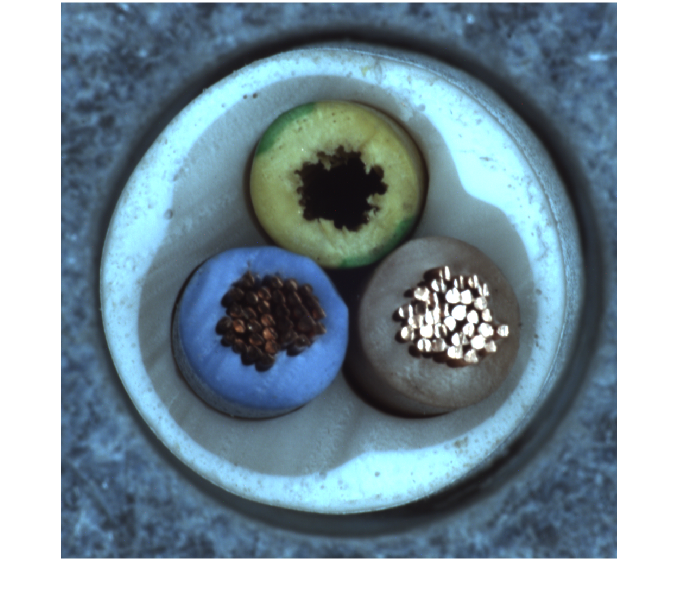

original = imread("00_data/cable/test/missing_wire/001.png");

I = imcrop(original,[110 110 800 800]);

grayImage = rgb2gray(I);

contrastImage = histeq(grayImage);

gausImage = imgaussfilt(grayImage, 5);

binImage = imbinarize(contrastImage, "adaptive");

se = eye(5);

dilImage = imdilate(binImage, se);
eroImage = imerode(dilImage, se);

closedImage = imopen(binImage,se);

img = closedImage;

imshow(original)

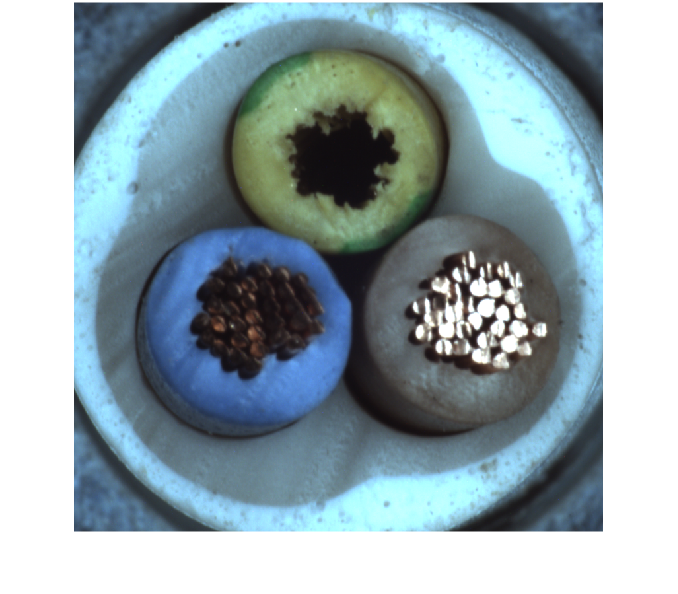

imshow(I)

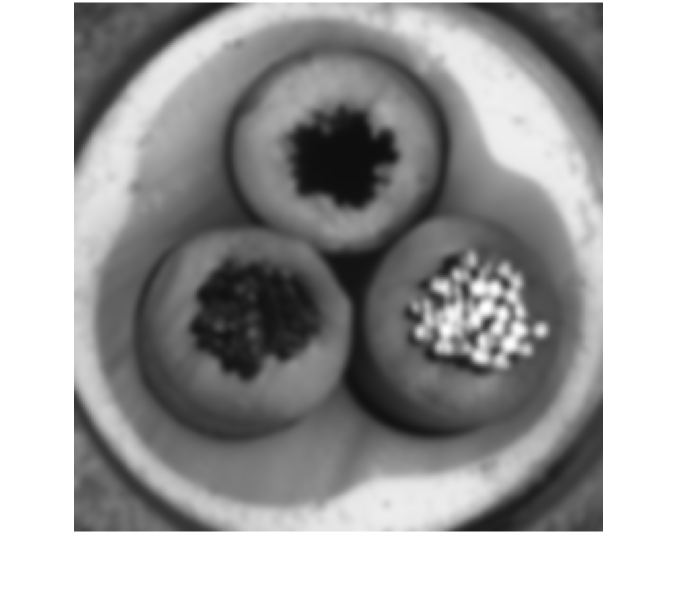

imshow(gausImage)

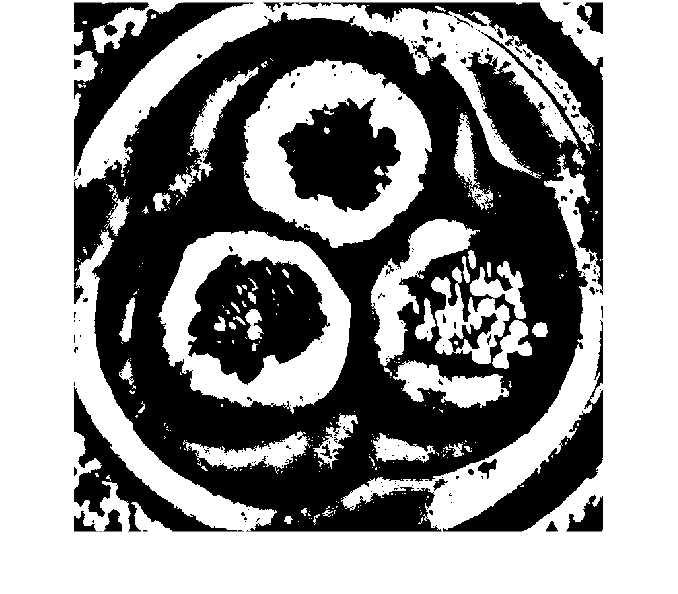

imshow(binImage)

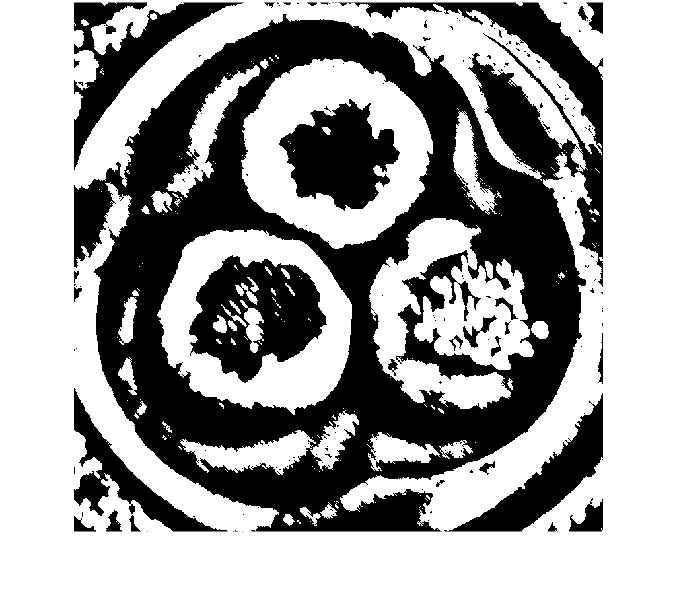

imshow(dilImage)

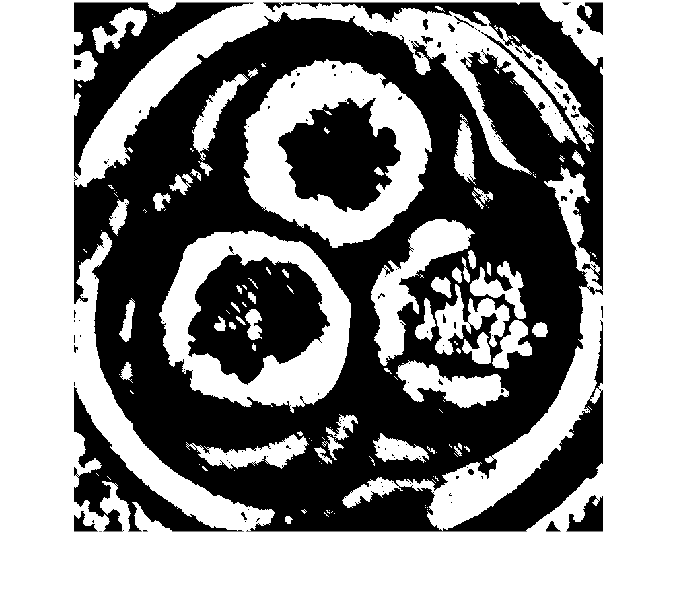

imshow(img)